# Honours Live Script 9

## Load Data

if ~exist("workspaceVarHonours", 'var')
    load matlabHonours.mat
    setInterpLatex()
end

## Save Data

if exist("workspaceVarHonours", 'var')
    clearVarsArray = clearVars();
    clear(clearVarsArray{:})
    clear clearVarsArray
    save matlabHonours.mat
end

% set the default intepreter to latex
setInterpLatex()

## Contents

Setting ICs (again)

Investigating Running of Full Metapopulation Model vs Partial Metapopulation Models

Setting ICs (again again)

Bugfixing

Analytical Exploration Testing

Loading in Sev's data

## Assumptions Made

% to avoid issues with the wrong variables being stored along with storage,
% I've removed some of the older connectivity matrices

% also I am changing the ideas behind the runMPASimulation code, so that it
% will run the entire GBR-wide population model, to ensure that fringing
% reefs in each of the study areas retain competitive populations and hence
% have the potential to be selected

% also I changed the plotSelectionHeatmap() code, so it will no longer work
% in previous scripts

## Notes

% fuck, at some point should go back and look at where the mpa selection
% using applyMPT() was originally done, so that I can compare with the
% chooseMPA() method

% at some point, should check that the new implementation of applyMPT() is
% actually reaching the point at which the boundary values are calculated

% because this optimisation shit is getting kinda cooked, is it maybe a
% better idea to instead be looking into reducing the areas I'm looking
% into, down to say 80 reefs instead?

## Setting ICs (again)

% fuck I'm gonna do this again like a little troglodyte, for a start going
% to use the same randStruct between runs
rng(22)
tWarmup = 300;
randStructInitCond.randType = "sequence";
randStructInitCond.sequence = randi(length(conMatsCT), 1, tWarmup - 1);

% also set up an area structure for the whole GBR
areaStructGBR = struct();
areaStructGBR.areas = areasCT;
areaStructGBR.conMats = conMatsCT;

% ALSO add the indices into the original matrices into the areaStructs
areaStructSwains.reefInds = find(reefIndsSwains);
areaStructTowns.reefInds = find(reefIndsTowns);
areaStructNorth.reefInds = find(reefIndsNorth);

length(areaStructSwains.reefInds)

ans = 100

length(areaStructTowns.reefInds)

ans = 100

length(areaStructNorth.reefInds)

ans = 100

% I'm gonna clear some shit here
clear conMatsSwains conMatsTowns conMatsNorth

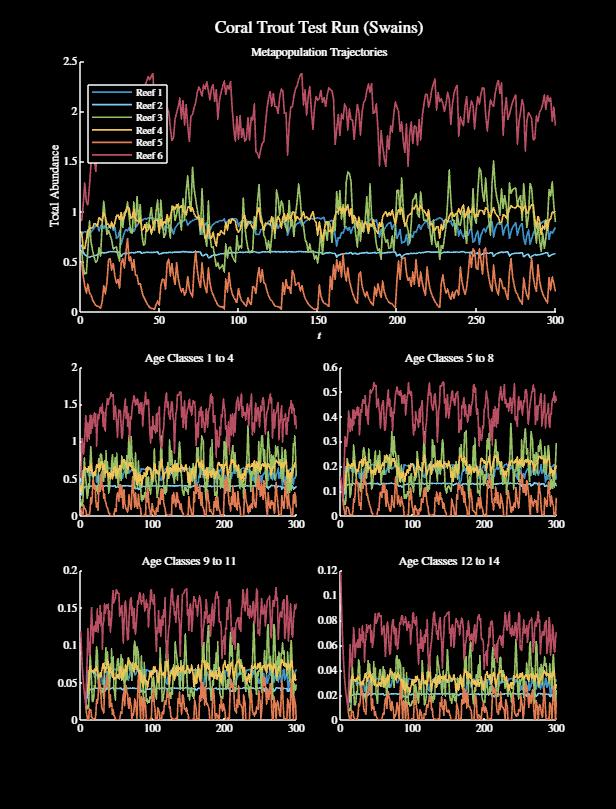

% first, let's look at the ICs for the Swains because why not
popInitTest = 0.05 * ones(length(areaStructSwains.conMats{1}), 14);
popMatTest = baseMetapopModel(areaStructSwains.conMats, ...
    areaStructSwains.areas, popInitTest, 300, specStructCT, ...
    randStructInitCond);

% visualise some of the population trajectories
% visualise a random selection of the reefs
var1 = [1, 4, 5, 6, 78, 30];
tL = visualiseMetapop(popMatTest(var1, :, :), 1:300);
title(tL, "Coral Trout Test Run (Swains)", 'Interpreter', 'Latex')
darkFig()
figResize(1.75)


% either way this is fine, so let's call that the initial population
areaStructSwains.initPop = mean(popMatTest(:, :, 201:300), 3);
clear popMatTest

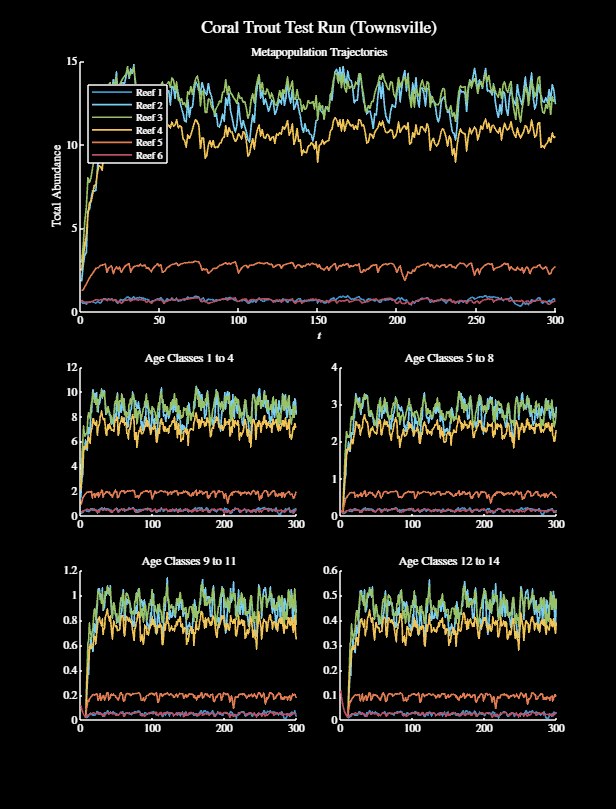

% let's now setup the initial conditions for Townsville
popInitTest = 0.05 * ones(length(areaStructTowns.conMats{1}), 14);
popMatTest = baseMetapopModel(areaStructTowns.conMats, ...
    areaStructTowns.areas, popInitTest, 300, specStructCT, ...
    randStructInitCond);

% visualise some of the population trajectories
var1 = randi(nReefsTowns, 1, 6);
tL = visualiseMetapop(popMatTest(var1, :, :), 1:300);
title(tL, "Coral Trout Test Run (Townsville)", 'Interpreter', 'Latex')
darkFig()
figResize(1.75)


% let's call that the initial population
areaStructTowns.initPop = mean(popMatTest(:, :, 201:300), 3);
clear popMatTest

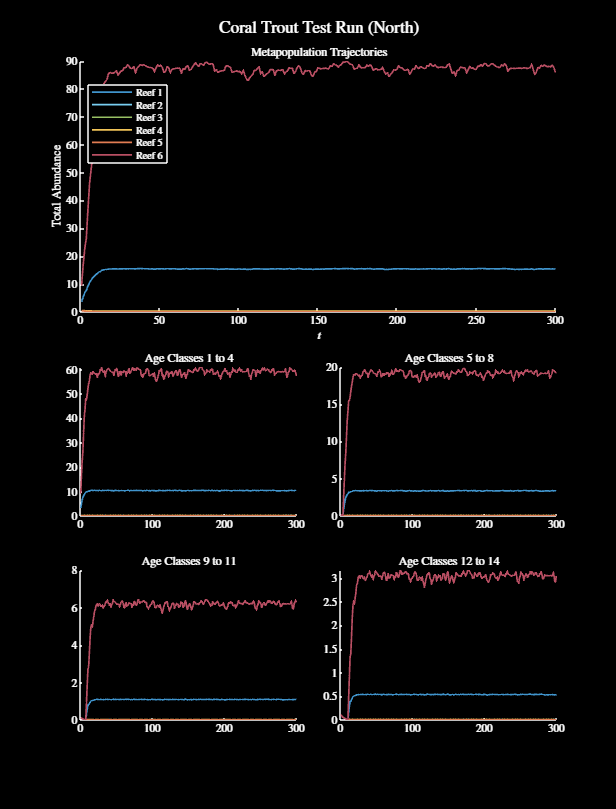

% finally, let's set up the ICs for the north region
popInitTest = 0.05 * ones(length(areaStructNorth.conMats{1}), 14);
popMatTest = baseMetapopModel(areaStructNorth.conMats, ...
    areaStructNorth.areas, popInitTest, 300, specStructCT, ...
    randStructInitCond);

% visualise some of the population trajectories
nReefsNorth = sum(reefIndsNorth);
var1 = randi(nReefsNorth, 1, 6);
tL = visualiseMetapop(popMatTest(var1, :, :), 1:300);
title(tL, "Coral Trout Test Run (North)", 'Interpreter', 'Latex')
darkFig()
figResize(1.75)


% let's call that the initial population
areaStructNorth.initPop = mean(popMatTest(:, :, 201:300), 3);
clear popMatTest

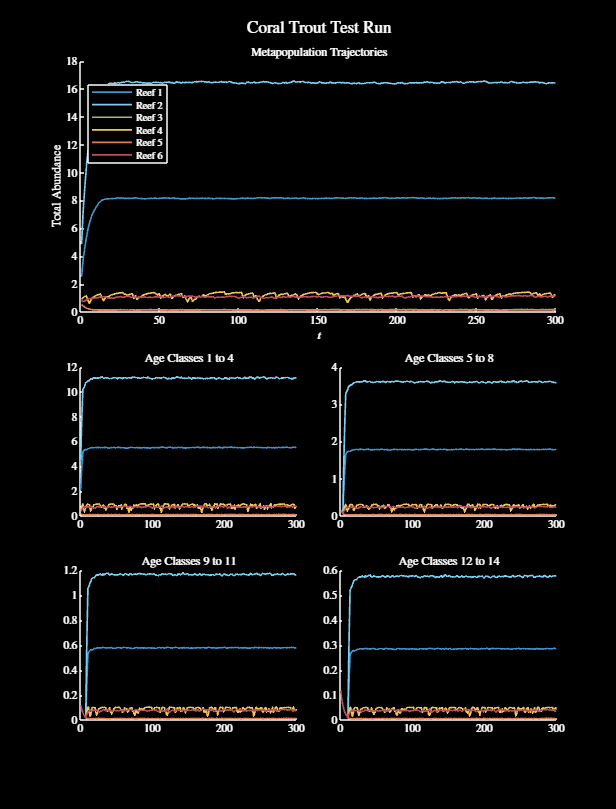

% extra finally, let's do the same for the entire GBR
popInitTest = 0.05 * ones(length(conMatsCT{1}), 14);
popMatTest = baseMetapopModel(areaStructGBR.conMats, ...
    areaStructGBR.areas, popInitTest, 300, specStructCT, ...
    randStructInitCond);

% visualise some of the population trajectories
nReefsCT = length(conMatsCT{1});
var1 = randi(nReefsCT, 1, 6);
tL = visualiseMetapop(popMatTest(var1, :, :), 1:300);
title(tL, "Coral Trout Test Run", 'Interpreter', 'Latex')
darkFig()
figResize(1.75)


% let's call that the initial population
areaStructGBR.initPop = mean(popMatTest(:, :, 201:300), 3);
clear popMatTest

## Investigating Running of Full Metapopulation Model vs Partial Metapopulation Models

% want to have a look here at whether the biomass content of the initial
% populations change much from running the full model, to running models of
% just the individual regions

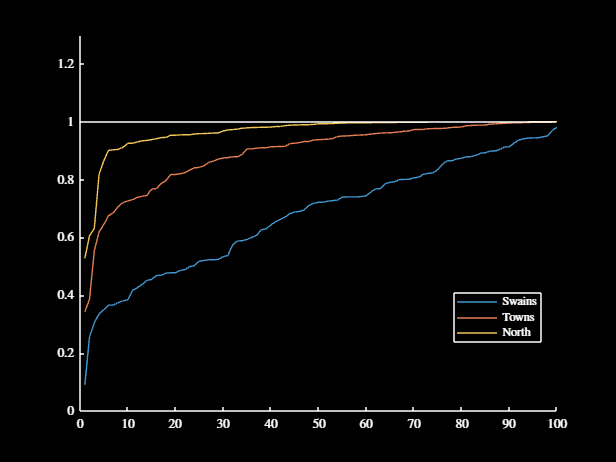

% alright - let's write come code which can compare the initial populations
% with the entire GBR running, to those with just the regional models
initBiomassGBR = areaStructGBR.initPop * specStructCT.massVec';
initBiomassSwains = areaStructSwains.initPop * specStructCT.massVec';
initBiomassTowns = areaStructTowns.initPop * specStructCT.massVec';
initBiomassNorth = areaStructNorth.initPop * specStructCT.massVec';

% let's now look at the ratios between the biomasses, and plot them
figure
hold on
plot(sort(initBiomassSwains ./ initBiomassGBR(areaStructSwains.reefInds)))
plot(sort(initBiomassTowns ./ initBiomassGBR(areaStructTowns.reefInds)))
plot(sort(initBiomassNorth ./ initBiomassGBR(areaStructNorth.reefInds)))
yline(1)
axis([0, 100, 0, 1.3])
legend("Swains", "Towns", "North", 'Location', 'best')
darkFig()


% based on the above results, it seems pretty reasonable to be runnning the
% full model for population's sake, but then only optimising on the
% sections we run

## Setting ICs (again again)

% so now that we're on the same page that running the full GBR model is
% necessary, it's then a good idea to set the ICs for each area based on
% the numbers gained from running the whole GBR
areaStructSwains.initPop = areaStructGBR.initPop(areaStructSwains.reefInds, :);
areaStructTowns.initPop = areaStructGBR.initPop(areaStructTowns.reefInds, :);
areaStructNorth.initPop = areaStructGBR.initPop(areaStructNorth.reefInds, :);

## Bugfixing

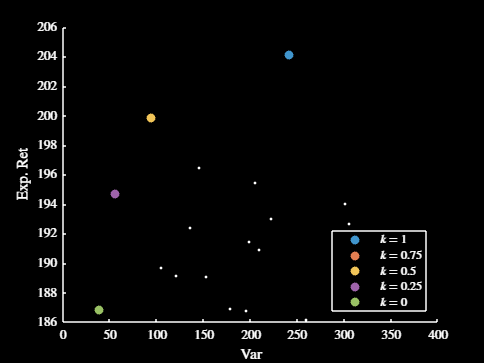

% something is clearly, CLEARLY fucked with my methods

% a good idea as a starting point, would be to apply MPT to a very
% simplified example, and ensure that my code is working as intended for an
% example where I can clearly see what the f*cbk (fuck) is going on

% gonna first create a simple case and test whether applyMPT() can solve it
% - then I'll go a step back, and maybe see if I can get identical results
% from solving using chooseMPA()

% without further adieu, let's do this boys LEEEEROY
rng(2203)
nAssets = 100;
covMat = 2 * rand(nAssets, nAssets) - 1;
covMat = covMat' * covMat;
variances = diag(covMat);
expReturns = 8 + rand(nAssets, 1) + 4 * sqrt(variances);

% generate some time series data, and set the rng
timeSeriesMat = mvnrnd(expReturns, covMat, 30);

% apply MPT for sets of different weights while calculating the boundary
% values
portVec = cell(1, 5);
portRet = zeros(1, 5);
portVar = zeros(1, 5);
var1 = [1, 0.75, 0.5, 0.25, 0];
for i = 1:5
    [portVec{i}, portRet(i), portVar(i)] = applyMPT(timeSeriesMat', var1(i), ...
        "discrete", 6, ones(size(expReturns)), [], "calcBoundVals");
end

% % apply MPT withoug calculating the boundary values
% portVec4 = cell(1, 5);
% portRet4 = zeros(1, 5);
% portVar4 = zeros(1, 5);
% var1 = [1, 0.75, 0.5, 0.25, 0];
% for i = 1:5
%     [portVec4{i}, portRet4(i), portVar4(i)] = applyMPT(timeSeriesMat', ...
%         var1(i), "discrete", 6, ones(size(expReturns)));
% end

% form a bunch of random portfolios
randPorts = cell(1, 20);
randPortsRet = zeros(1, 20);
randPortsVar = zeros(1, 20);
for i = 1:length(randPorts)
    randPorts{i} = randi(length(expReturns), [6, 1]);
    randPortsRet(i) = mean(sum(timeSeriesMat(:, randPorts{i}), 2));
    randPortsVar(i) = var(sum(timeSeriesMat(:, randPorts{i}), 2));
end

% plot the decision space
figure
hold on
for i = 1:5
    plot(portVar(i), portRet(i), '.', 'MarkerSize', 20, 'Color', ...
        getColour(i))
end
% for i = 1:5
%     plot(portVar4(i), portRet4(i), 'o', 'MarkerSize', 20, 'Color', ...
%         getColour(i))
% end
plot(randPortsVar, randPortsRet, 'k.')
xlabel("Var")
ylabel("Exp. Ret")
legend("$k = 1$", "$k = 0.75$", "$k = 0.5$", "$k = 0.25$", "$k = 0$", ...
    'location', 'southeast')
darkFig()


% the above is doing fine with rng 23, 17, 6, and 48 for 20 assets

% 6 had some slight discrepencies for the case in which boundary values
% were not calculated but very minor

% upping it to 80 assets and yep - for the boundary calculated portfolios,
% the k = 1 case is fucked for some stupid reason for rng 3, it's a little
% shit for rng 24, fine for rng 38, fine for rng 96, completely cooked for
% 20 fine for 123, fucked on 90, a bit cooked on 100 but not too bad

% upping it to 100 just for the bit, rng 100 is ok, it's not great for 24,
% it's ok for 39 I guess, 94 is good, cooked again on 230, fine on 2203

% it seems like the discrepencies could be due to convergence to local
% minima maybe - let's have a look at the boundvals calculated over a few
% different runs - note that due to this problem being of a vastly
% different size, it's possible that we could converge to the same value
% each time

% apply MPT with the same weights repeatedly
portVec2 = cell(1, 5);
portRet2 = zeros(1, 5);
portVar2 = zeros(1, 5);
for i = 1:5
    [portVec2{i}, portRet2(i), portVar2(i)] = applyMPT(timeSeriesMat', 1, ...
        "discrete", 6, ones(size(expReturns)));
end
portVec3 = cell(1, 5);
portRet3 = zeros(1, 5);
portVar3 = zeros(1, 5);
for i = 1:5
    [portVec3{i}, portRet3(i), portVar3(i)] = applyMPT(timeSeriesMat', 0, ...
        "discrete", 6, ones(size(expReturns)));
end

% plot the decision space
figure
hold on
for i = 1:5
    plot(portVar2(i), portRet2(i), '.', 'MarkerSize', 20, 'Color', ...
        getColour(i))
end
for i = 1:5
    plot(portVar3(i), portRet3(i), 'o', 'MarkerSize', 20, 'Color', ...
        getColour(i))
end
plot(randPortsVar, randPortsRet, 'k.')
xlabel("Var")
ylabel("Exp. Ret")
darkFig()

% this is fine, there is a little bit of disagreement between the minimum
% variance protfolios, however the max expected return is chillin

% now that I've set the rng()'s for 0 or 1 weightings, as expected the
% portfolios returned are identical (this is good) (idk maybe it's bad but
% whatever who gives a f*c k (fuck)

% finally, let's use some breakpoints to ensure that once and for all, the
% arguments and their defaults are acting as intended
applyMPT(timeSeriesMat', 0.5, "discrete", 6, ones(size(expReturns)), [], ...
    "calcBoundVals", "parallel");

% seems to work well which is cool - I can now start to look into the
% results, and hope that things are ok

clear expReturns covMat expVals vars portVec portRet portVar randPorts ...
    portVec2 portRet2 portVar2 portVec3 portRet3 portVar3 portVec4 ...
    portRet4 portVar4 timeSeriesMat

## Analytical Exploration Testing

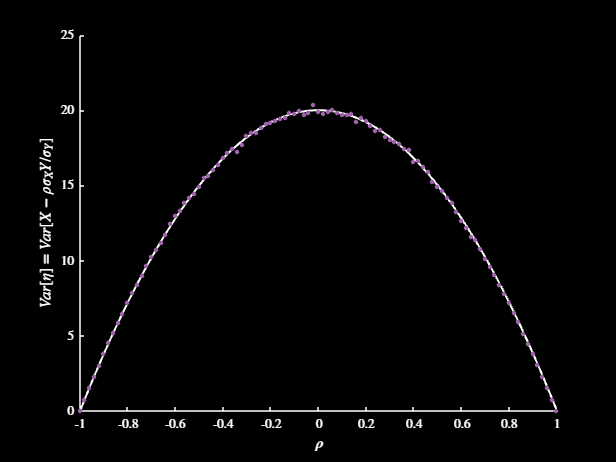

% I want to look into the idea of the rho coefficients and scaling etc when
% we're looking at two correlated random number streams

% it's possible however, that there isn't as much of a transferrable
% relationship if you are trying to be agnostic about the distributions, so
% idk maybe I should wait to ask Mike about this

% let's set up a vector of correlations
corrVec = linspace(-1, 1, 101);
meansVec = zeros(size(corrVec));
varVec = zeros(size(corrVec));
nReps = 1000;

% let's set up some variances, and have means as zero
var1 = 3;
var2 = 20;
meanVec = [0, 0];

% let's loop over the correlations, generate some multivariate normal
% streams, and then calculate the variances in their difference, to
% determine whether there is a relationship with that quantity and the
% correlation
for c = 1:length(corrVec)

    % average the results over a number of repetitions
    for r = 1:nReps

        % form the random streams
        sigmaMat = [var1, sqrt(var1) * sqrt(var2) * corrVec(c); ...
            sqrt(var1) * sqrt(var2) * corrVec(c), var2];
        randVars = mvnrnd(meanVec, sigmaMat, 30);

        % determine the difference between the correlation trick thing and the
        % true quantity I think fuck ok this might be a bit hard but she'll be
        % right
        diffVec = randVars(:, 2) - sqrt(var2) * corrVec(c) * randVars(:, 1) ...
            / sqrt(var1);
        meansVec(c) = meansVec(c) + mean(diffVec) / nReps;
        varVec(c) = varVec(c) + var(diffVec) / nReps;

    end

end

% let's try and write a function that would be able to predict these
% numerical results analytically - it looks like it should be a quadratic,
% and will always intercept the x axis at 1 and -1
funcIdea = -var2 * corrVec .^2 + var2;

% plot the results
figure
hold on
plot(corrVec, funcIdea, 'k', 'LineWidth', 1.5)
plot(corrVec, varVec, '.', 'Color', getColour('p'), 'MarkerSize', 10)
xlabel("$\rho$")
ylabel("$Var[\eta] = Var[X - \rho \sigma_X Y / \sigma_Y]$")
darkFig()

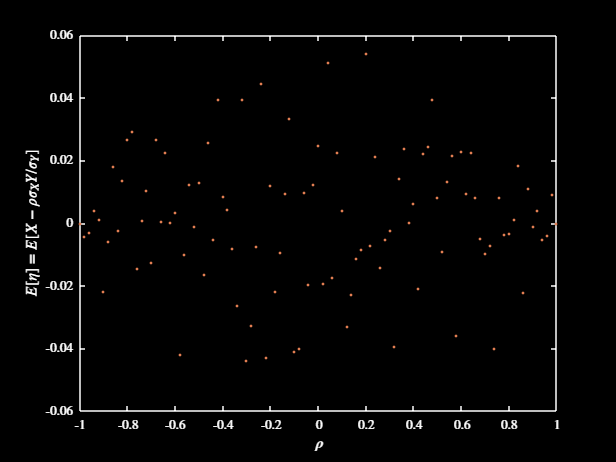


% note that the means are all 0 which is great too
figure
plot(corrVec, meansVec, '.', 'Color', getColour('o'))
xlabel("$\rho$")
ylabel("$E[\eta] = E[X - \rho \sigma_X Y / \sigma_Y]$")
darkFig()

% idea - could do a simulation here to determine whether the 

% just to demonstrate what I mean to Alastair, let's plot some of the time
% series for some example
% rng(1)
corrVal = 0.5;

% let's set up some variances, and have means as zero
var1 = 3;
var2 = 20;
meanVec = [0, 0];

% let's create a time-series for each
sigmaMat = [var1, sqrt(var1) * sqrt(var2) * corrVal; ...
    sqrt(var1) * sqrt(var2) * corrVal, var2];
randVars = mvnrnd(meanVec, sigmaMat, 30);

% create the eta term
trueCorr = corr(randVars(:, 1), randVars(:, 2))

trueCorr = 0.2721

etaVec = randVars(:, 2) - (sqrt(var2) * trueCorr * randVars(:, 1)) / sqrt(var1);
corr(etaVec, randVars(:, 1))

ans = 0.0311

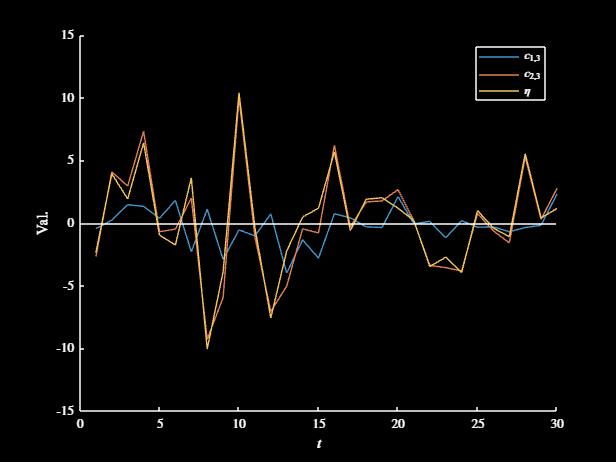


% plot the results
figure
hold on
plot(randVars(:, 1))
plot(randVars(:, 2))
plot(etaVec)
yline(0)
legend("$c_{1, 3}$", "$c_{2, 3}$", "$\eta$")
xlabel("$t$")
ylabel("Val.")
darkFig()


% check I've fucked something
var3 = (trueCorr * sqrt(var2) * randVars(:, 1)) / sqrt(var1) + etaVec;
sum(randVars(:, 2) - var3)

ans = -2.2204e-16

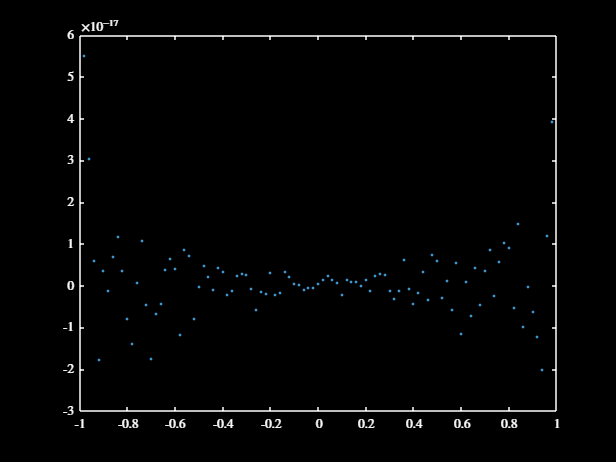

% repeat the above over a large number of trials
% let's set up a vector of correlations
corrVec = linspace(-1, 1, 101);
corrVec = corrVec(2:(end - 1));
corrC1RhoVec = zeros(size(corrVec));
corrC2RhoVec = zeros(size(corrVec));
nReps = 1000;

% let's set up some variances, and have means as zero
var1 = 3;
var2 = 20;
meanVec = [0, 0];

% let's loop over the correlations, generate some multivariate normal
% streams, and then calculate the variances in their difference, to
% determine whether there is a relationship with that quantity and the
% correlation
for c = 1:length(corrVec)

    % average the results over a number of repetitions
    for r = 1:nReps

        % form the random streams
        sigmaMat = [var1, sqrt(var1) * sqrt(var2) * corrVec(c); ...
            sqrt(var1) * sqrt(var2) * corrVec(c), var2];
        randVars = mvnrnd(meanVec, sigmaMat, 30);

        % determine the true correlations and variances
        % create the eta term
        trueCorr = corr(randVars(:, 1), randVars(:, 2));
        trueStd1 = std(randVars(:, 1));
        trueStd2 = std(randVars(:, 2));
        etaVec = randVars(:, 2) - (trueStd2 * trueCorr ...
            * randVars(:, 1)) / trueStd1;
        corrC1RhoVec(c) = corrC1RhoVec(c) + corr(etaVec, ...
            randVars(:, 1)) / nReps;
        corrC2RhoVec(c) = corrC2RhoVec(c) + corr(etaVec, ...
            randVars(:, 2)) / nReps;

    end

end

% plot the results
figure
plot(corrVec, corrC1RhoVec, '.')
darkFig()

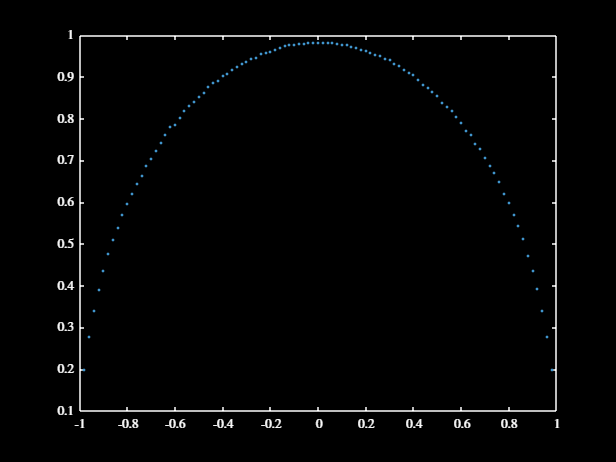


figure
plot(corrVec, corrC2RhoVec, '.')
darkFig()


% ok - does seem like they're truly independent, this is cool and good lets
% fucking GO


## Loading in Sev's data

% cd into the folder
cd ../Data/'Sev matrices'/

% the variables I care about are either normed_matrixCellnp_rp or
% normed_matrixCellp_rp - fuck it I'll just do the second one for now idfk

% load in all the data bit by bit
dirVar = dir();
namesVec = strings(1, length(dirVar) - 4);
monthVec = zeros(1, length(dirVar) - 4);
yearsVec = zeros(1, length(dirVar) - 4);
conMatsHawaii = cell(length(dirVar) - 4, 1);

% loop over each of the files
for f = 5:length(dirVar)

    % save the filename of the current matrix, so that I can find some
    % awesome and cool ways to sort it later
    namesVec(f - 4) = dirVar(f).name;

    % also save the month and year separately
    var1 = split(dirVar(f).name, "_");
    if var1(2) == "june"
        monthVec(f - 4) = 6;
    elseif var1(2) == "july"
        monthVec(f - 4) = 7;
    else
        monthVec(f - 4) = 8;
    end
    yearsVec(f - 4) = str2double(var1(3));
    
    % load in the matrix, first replacing all NaNs with zeros, and then
    % converting to sparse storage
    var1 = load(dirVar(f).name, "normed_matrixCellp_rp");
    var1 = var1.normed_matrixCellp_rp;
    var1(isnan(var1)) = 0;
    conMatsHawaii{f - 4} = sparse(var1);

end

% we can sort the stuff by just calculating a time in a crude and awesome
% and epic manner
timeVecHawaii = yearsVec + monthVec / 12;
[timeVecHawaii, var1] = sort(timeVecHawaii);
namesVecHawaii = namesVec(var1);
yearsVecHawaii = yearsVec(var1);
monthsVecHawaii = monthVec(var1);
var2 = conMatsHawaii;
for i = 1:length(conMatsHawaii)
    conMatsHawaii{i} = var2{var1(i)};
end
clear var1 var2 monthVec yearsVec dirVar namesVec 

namesVecHawaii

namesVecHawaii = 1×60 string array
    "hi_june_1993_norm.mat"    "hi_july_1993_norm.mat"    "hi_august_1993_norm.mat"    "hi_june_1994_norm.mat"    "hi_july_1994_norm.mat"    "hi_august_1994_norm.mat"    "hi_june_1995_norm.mat"    "hi_july_1995_norm.mat"    "hi_august_1995_norm.mat"    "hi_june_1996_norm.mat"    "hi_july_1996_norm.mat"    "hi_august_1996_norm.mat"    "hi_june_1997_norm.mat"    "hi_july_1997_norm.mat"    "hi_august_1997_norm.mat"    "hi_june_1998_norm.mat"    "hi_july_1998_norm.mat"    "hi_august_1998_norm.mat"    "hi_june_1999_norm.mat"    "hi_july_1999_norm.mat"    "hi_august_1999_norm.mat"    "hi_june_2000_norm.mat"    "hi_july_2000_norm.mat"    "hi_august_2000_norm.mat"    "hi_june_2001_norm.mat"    "hi_july_2001_norm.mat"    "hi_august_2001_norm.mat"    "hi_june_2002_norm.mat"    "hi_july_2002_norm.mat"    "hi_august_2002_norm.mat"    "hi_june_2003_norm.mat"    "hi_july_2003_norm.mat"    "hi_august_2003_norm.mat"    "hi_june_2004_norm.mat"    "hi_july_2004_norm.ma

% cd back out into the og folder
cd ../../Code/